# Homework 4

Math 3607, Autumn 2021

Xiaoya Gao

Gao.1666

## Problem 1 (Sliders moving along groove)

## Part(a) 

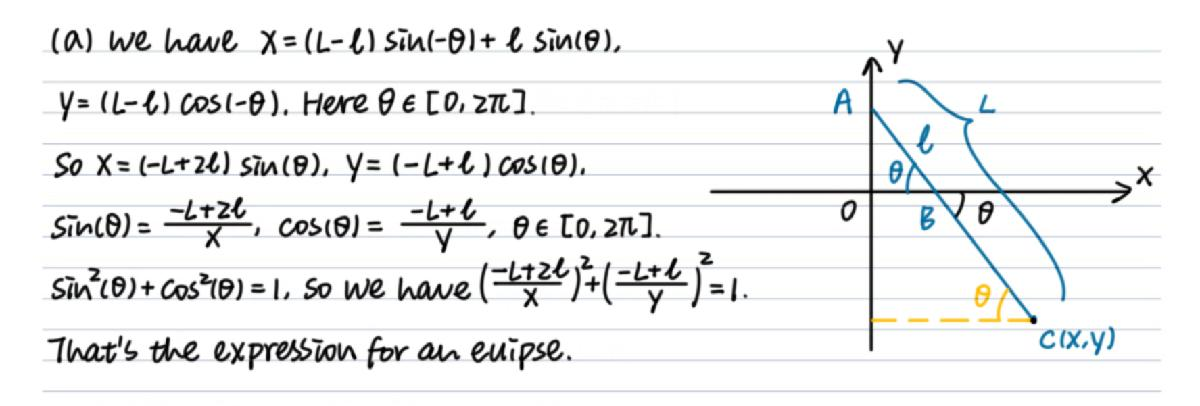

## Part(b) 

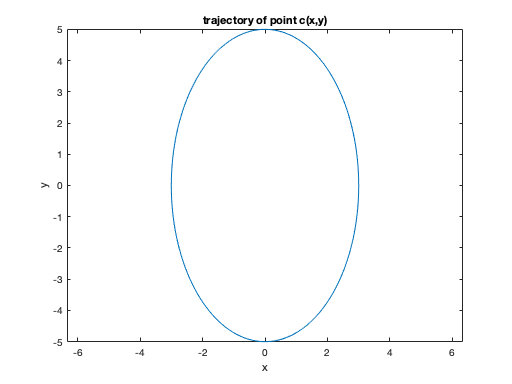

L = 7; l = 2;
th = linspace(0,2*pi,361);
x = (-L+2*l)*sin(th);
y = (L-l)*cos(th);
clf
plot(x,y);
axis equal
xlabel('x');
ylabel('y');
title('trajectory of point c(x,y)');

## Problem 2 (Spiral triangles to spiral polygons)

## Part(a)

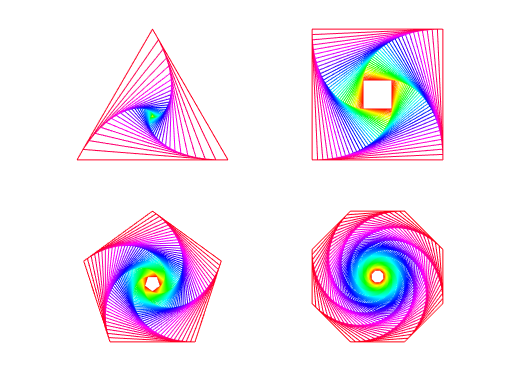

clf
subplot(2, 2, 1), spiralgon(3, 41, 4.5, -90);
subplot(2, 2, 2), spiralgon(4, 37, -2.5, 45);
subplot(2, 2, 3), spiralgon(5, 61, 3, -90);
subplot(2, 2, 4), spiralgon(8, 91, -4, 22.5);

## Problem 3 (Machine epsilon)

## Part(a)

format long
(8 + 4*eps) - 8

ans =      0


(8 + 4.01*eps) - 8

ans =      1.776356839400250e-15


## Part(b)

(16 - 4.01*eps) - 16

ans =     -1.776356839400250e-15


(16 - 4*eps) - 16

ans =      0


## Part(c)

We have that the number which follows $1=2^{0\;}$is $1+1\left\lbrack \mathrm{eps}\right\rbrack \;=2^0 +2^0 \left\lbrack \mathrm{eps}\right\rbrack$; 

the number which follows $2=2^{1\;}$is $2+2\left\lbrack \mathrm{eps}\right\rbrack \;=2^1 +2^1 \left\lbrack \mathrm{eps}\right\rbrack$; 

 the number which follows $4=2^{2\;}$is $4+4\left\lbrack \mathrm{eps}\right\rbrack \;=2^2 +2^2 \left\lbrack \mathrm{eps}\right\rbrack$;

the number which follows $8=2^{3\;}$is $8+8\left\lbrack \mathrm{eps}\right\rbrack \;=2^3 +2^3 \left\lbrack \mathrm{eps}\right\rbrack$; 

Therefore, the number which follows $1024=2^{10\;}$is $1024+1024\left\lbrack \mathrm{eps}\right\rbrack \;=2^{10} +2^{10} \left\lbrack \mathrm{eps}\right\rbrack$, respectively. 

We have that the number which precedes $2=2^{1\;}$is $2-1\left\lbrack \mathrm{eps}\right\rbrack \;=2^1 -2^0 \left\lbrack \mathrm{eps}\right\rbrack$; 

the number which precedes $4=2^{2\;}$is $4-2\left\lbrack \mathrm{eps}\right\rbrack \;=2^2 -2^1 \left\lbrack \mathrm{eps}\right\rbrack$; 

the number which precedes $8=2^{3\;}$is $8-4\left\lbrack \mathrm{eps}\right\rbrack \;=2^3 -2^2 \left\lbrack \mathrm{eps}\right\rbrack$;

the number which precedes $16=2^{4\;}$is $16-8\left\lbrack \mathrm{eps}\right\rbrack \;=2^4 -2^3 \left\lbrack \mathrm{eps}\right\rbrack$; 

Therefore, the number which precedes $1024=2^{10\;}$is $1024-512\left\lbrack \mathrm{eps}\right\rbrack \;=2^{10} -2^9 \left\lbrack \mathrm{eps}\right\rbrack$, respectively. 

So we should verify that the number in the computer which follows $1024\;$is $1024+1024\left\lbrack \mathrm{eps}\right\rbrack \;$the number which precedes $1024\;$is $1024-512\left\lbrack \mathrm{eps}\right\rbrack \;$

by numerically calculating $1024\;+512\left\lbrack \mathrm{eps}\right\rbrack ,1024\;+512\ldotp 01\left\lbrack \mathrm{eps}\right\rbrack ,1024-256\left\lbrack \mathrm{eps}\right\rbrack ,\mathrm{and}\;1024\;-256\ldotp 01\left\lbrack \mathrm{eps}\right\rbrack \ldotp \;$

(1024 + 512*eps) - 1024

ans =      0


(1024 + 512.01*eps) - 1024

ans =      2.273736754432321e-13


(1024 - 256*eps) - 1024

ans =      0


(1024 - 256.01*eps) - 1024

ans =     -1.136868377216160e-13


## Problem 4 (Catastrophic cancellation)

## Part(a)

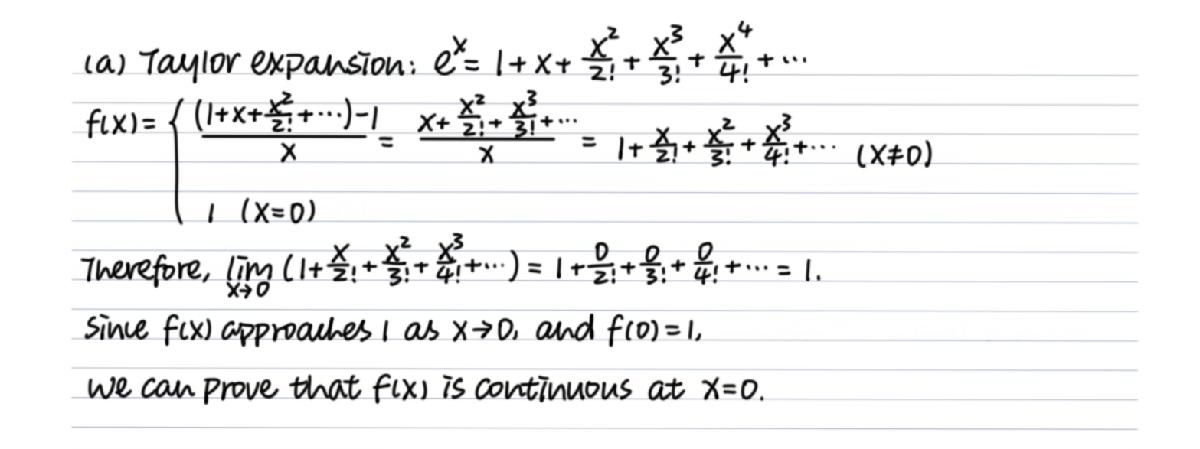

## Part(b)

format long
k = [1:20];
x = (10.^(-k));
f = (exp(x)-ones(1,20))./x;

f1 = (exp(x)-ones(1,20))./(log(exp(x)));

f2 = (expm1(x))./x;

x = x'; f = f'; f1 = f1'; f2 = f2';

disp([x f f1 f2]);

  Columns 1 through 3

   0.100000000000000   1.051709180756477   1.051709180756476
   0.010000000000000   1.005016708416795   1.005016708416806
   0.001000000000000   1.000500166708385   1.000500166708342
   0.000100000000000   1.000050001667141   1.000050001666708
   0.000010000000000   1.000005000006965   1.000005000016667
   0.000001000000000   1.000000499962184   1.000000500000167
   0.000000100000000   1.000000049433680   1.000000050000002
   0.000000010000000   0.999999993922529   1.000000005000000
   0.000000001000000   1.000000082740371   1.000000000500000
   0.000000000100000   1.000000082740371   1.000000000050000
   0.000000000010000   1.000000082740371   1.000000000005000
   0.000000000001000   1.000088900582341   1.000000000000500
   0.000000000000100   0.999200722162641   1.000000000000050
   0.000000000000010   0.999200722162641   1.000000000000005
   0.000000000000001   1.110223024625157   1.000000000000000
   0.000000000000000                   0                 NaN
 

## Part(c)

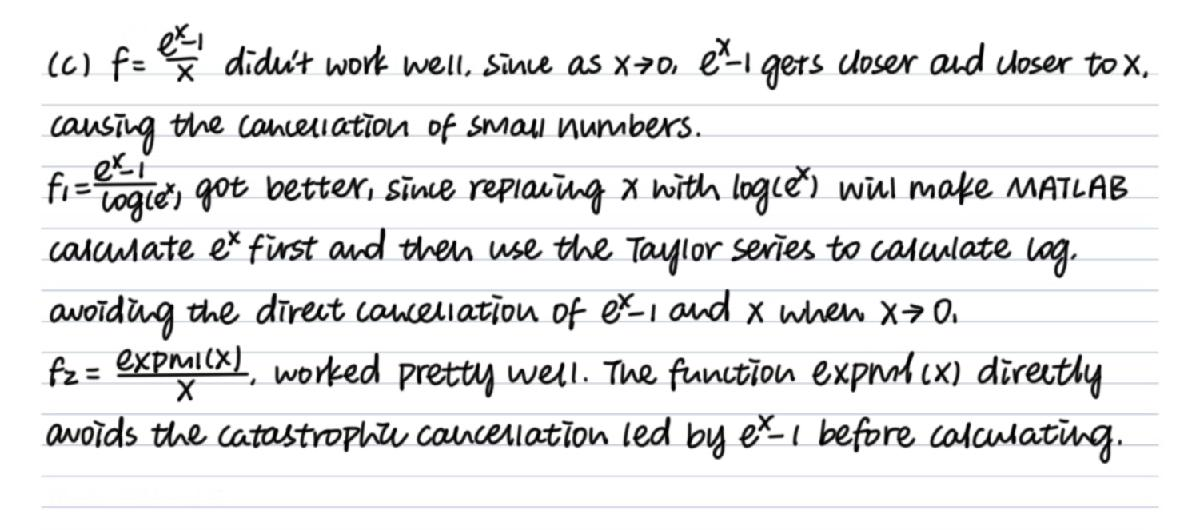

## Problem 5 (Inverting hyperbolic cosine)

## Part(a)

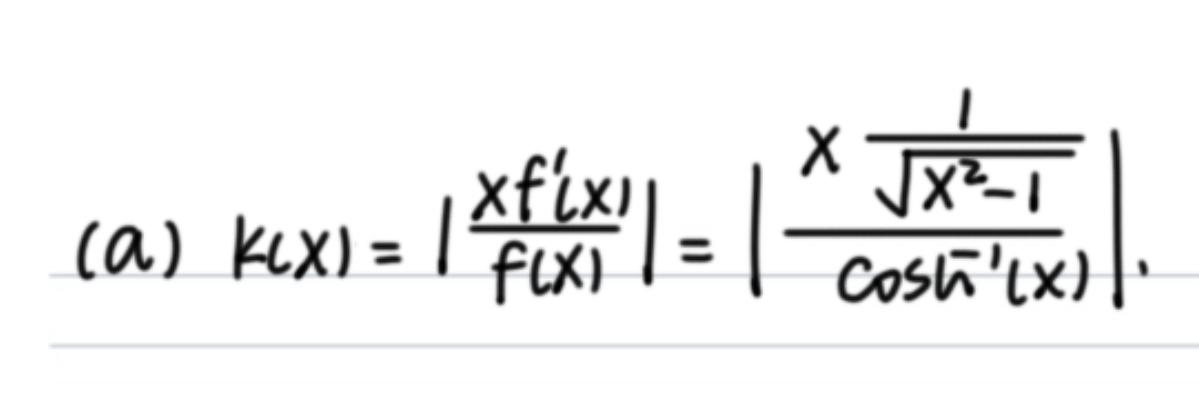

format long
t = [-4:-4:-16];
x = cosh(t);
kf = abs((x./sqrt(x.^2 - ones(1,4))) ./ (acosh(x)))';
disp(kf);

   0.250167787600421
   0.125000028133797
   0.083333333339625
   0.062500000000002



## Part(b)

Here `Tb `= the t calculated using $t=\log \left(x-\sqrt{x^2 -1}\right)$, and `rel_err_b `= the relative error caluclated in this part,  part(b).

Tb = log(x - sqrt(x.^2 - ones(1,4)));
rel_err_b = (Tb - t) ./ t;

t = t'; Tb = Tb'; rel_err_b = rel_err_b';
disp([t Tb rel_err_b]);

  -4.000000000000000  -4.000000000000046   0.000000000000012
  -8.000000000000000  -8.000000000171090   0.000000000021386
 -12.000000000000000 -12.000000137072186   0.000000011422682
 -16.000000000000000 -15.998624871201619  -0.000085945549899



## Part(c)

Here `Tc `= the t calculated using $t=-2\log \left(\sqrt{\frac{x+1}{2}}+\sqrt{\frac{x-1}{2}}\right)$, and `rel_err_c `= the relative error caluclated in this part,  part(c).

format long
t = t';
Tc = -2*log(sqrt((x+ones(1,4))./2) + sqrt((x-ones(1,4))./2));
rel_err_c = (Tc - t) ./ t;

t = t'; Tc = Tc'; rel_err_c = rel_err_c';
disp([t Tc rel_err_c]);

    -4    -4     0
    -8    -8     0
   -12   -12     0
   -16   -16     0



## Part(d)

The formula $\left(*\right)$ is unstable

.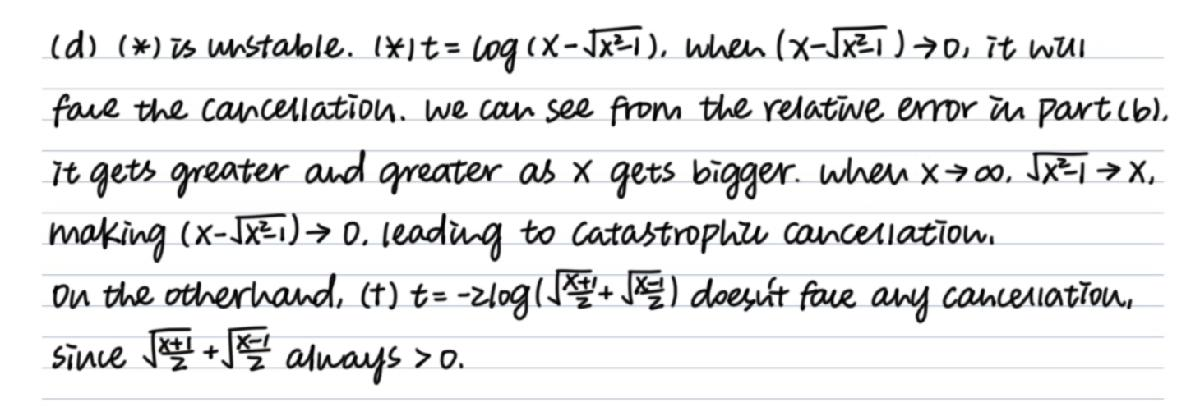

## Part(a), Problem 2, spiralgon function

Linspace(0,360,n+1) generates a vector with 360 evenly spaced points between 0 and n+1;

We have that the sum of the internal angles of polygon with n vertices is (n-2)*180°, so half angle on their vertices = (n-2)*180°/2n. 

Using the formula $\frac{\sin \;a}{A}=\frac{\sin \;b}{B}=\frac{\sin \;c}{C}$ given in lecture 9 sildes, we have $\frac{\sin \;\left(\left(n-2\right)*180°/2n\right)}{1}=\frac{\sin \;\left(180°-\left(\left(n-2\right)*180°/2n\right)-\mathrm{abs}\left(d_- \mathrm{angle}\right)\right)}{s}$

For the scaling factor s, s = $\frac{\sin \;\left(180°-\left(\left(n-2\right)*180°/2n\right)-\mathrm{abs}\left(d_- \mathrm{angle}\right)\right)}{\sin \;\left(\left(n-2\right)*180°/2n\right)}\;=\;\frac{\sin \;\left(180°-\left(90°-180°/n\right)-\mathrm{abs}\left(d_- \mathrm{angle}\right)\right)}{\sin \;\left(90°-180°/n\right)}\;=\frac{\;\sin \;\left(90°+180°/n-\mathrm{abs}\left(d_- \mathrm{angle}\right)\right)}{\sin \;\left(90°-180°/n\right)}\ldotp$

function V = spiralgon(n, m, d_angle, d_rot)
% SPIRALGON plots spiraling regular n-gons
% input: n = the number of vertices
%        m = the number of regular n-gons
%        d_angle = the degree angle between successive n-gons
%               (can be positive or negative)
%        d_rot = the degree angle by which the innermost n-gon
%              is rotated
% output: V = the vertices of the outermost n-gon

    th = linspace(0, 360, n+1) + d_rot;
    V = [cosd(th);
    sind(th)];
    C = colormap(hsv(m));
    s = sind(90+(180/n) - abs(d_angle))/sind(90-(180/n));
    R = [cosd(d_angle) -sind(d_angle);
    sind(d_angle) cosd(d_angle)];
    hold off
    for i = 1:m
        if i > 1
           V = s*R*V;
        end
        plot(V(1,:), V(2,:), 'Color', C(i,:))
        hold on
    end
    set(gcf, 'Color', 'w')
    axis equal, axis off
end